## Szimulátor

Pontosan ez a NPN tranzisztor nem szimulálható, viszont egy közelítő áramkör összerakható.

[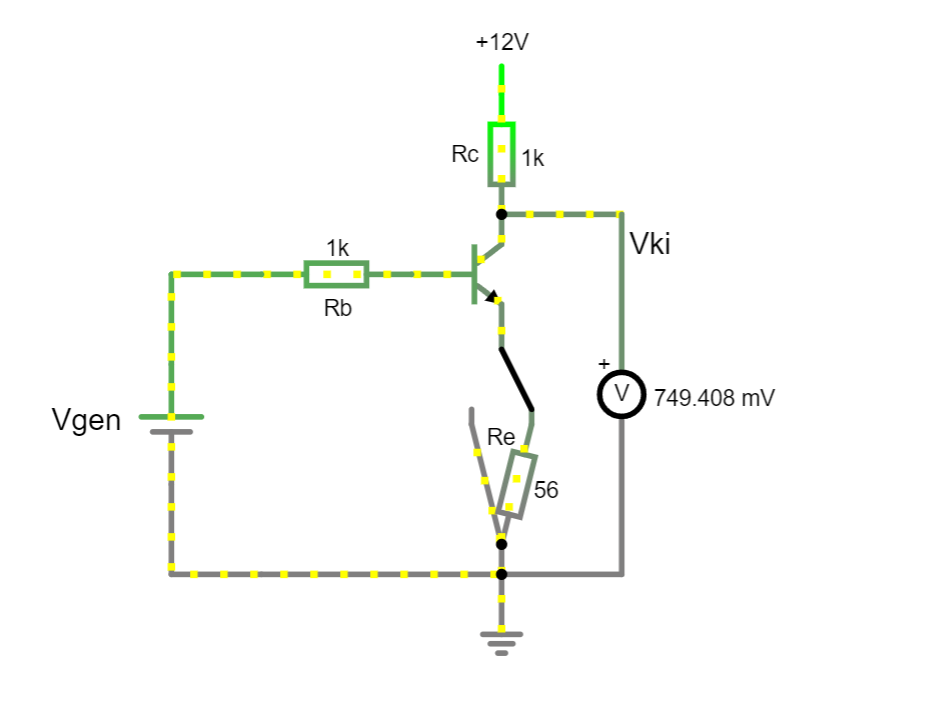](https://falstad.com/circuit/circuitjs.html?ctz=CQAgjCAMB0l3BWcMBMcUHYMGZIA4UA2ATmIxAUgpABZsKBTAWjDACgAXcQqtPEPgPxRwUaAkJgMBGimIIwJbHLGEExbHll5lPFJQhg4IACYMAZgEMArgBsObAMpD+KGr2Eo8-KlSu2AZwYRFDYAd3BiFAFvFxBsBGjINgAnATcY12EEpIpCcLiUDME3XwLBMCi4qUIoVOqMWoqwXKM4NgAPcDxDGn5KpDAFWnBogCUAY06hXlIBIfjIaJpRkDGGesUPfjxtkTbkrtZ6FFxR12x6FZa1gCM2AHM47EIs-ndfOojBHOfXr7+OyoLx8bAAbvFospgdF9LVPu5wNByJ8YAgCrt4v9lFjQREcSDIZCyvjYRIiYJkqS4pjKWwxtUboJMQiqDdUeJysIagIMNEeVTAbyof9DrzapVyHIslRrrUAGoAawAltMmDi5BAkHIVnKQPKHgwAHZsAAOwvAjQthPoZU04BWADEIJ8jCAWPqAPb2SyGthAA)

## 1. feladat

[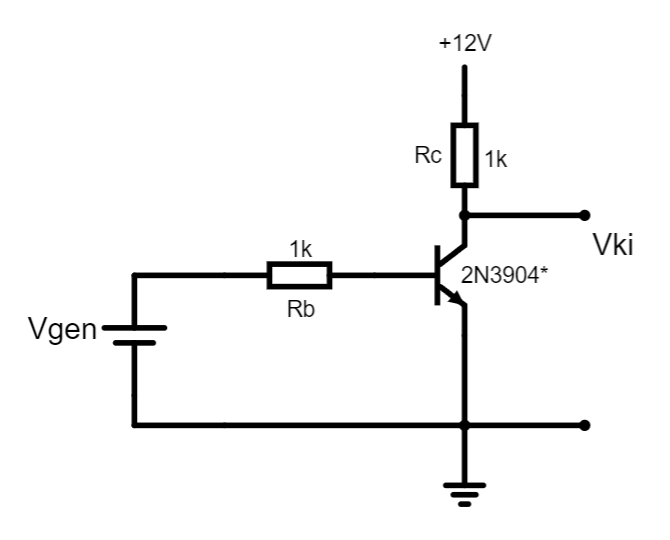](https://falstad.com/circuit/circuitjs.html?ctz=CQAgLCAMB0l3BWEBGGAmOaDsWDMkAONANgE5SsQFIrxcqBTAWmWQCgAXFYmjAkPgMJQUIFsmjkp5YrizxIaFNAzSZuVq1LN+qGgBMGAMwCGAVwA2HNgHch-NGgiCnNSLfspSSwcizEoNgAnTz8A32QlGj13AA8UAmQUMF1SJGQEJIhIkAAlAGNg7l5hAhL+aPg2eNZ6NHwUNAdcemylXIAjNgBzTyaHYVwMEXc7FzBygQIKjxdpkDKpmYA3ECGBLCV1wTdwXf3oBA9F-rWfedGzpavsKI9t0sn3XNCcwUXdicaRqEPZ4TCGyUgMucwcm2ucQ2AWQFAEpAGNGyAQAagBrACW1TEaCQTmBPjASGRIBR3QYADtsRhwm8ED4MuBvmgAHK4UiQMAAKjYuF0NAAYkldqgxEkUQB7KwmclsIA)

V_in = [0.311 0.6 ...
    0.634 0.66 0.68 0.7 0.72 0.738 ...
    0.76 0.77];
V_out = [11.3 11.34 ...
    11.2 10.84 10.6 8.99 5.28 2.11 ...
    0.098 0.09];

R = 6800;

I_b = V_in ./ R;

measurements = table(V_in', V_out', (I_b .* 10^3)', ...
    'VariableNames', ["Bemeneti feszültség (V)", "Kimeneti feszültség (V)", "Bemeneti áramerősség (mA)"]);
disp("Mért értékek");

Mért értékek


display(measurements);

measurements = 10×3 table
    Bemeneti feszültség (V)    Kimeneti feszültség (V)    Bemeneti áramerősség (mA)
    _______________________    _______________________    _________________________

             0.311                       11.3                     0.045735         
               0.6                      11.34                     0.088235         
             0.634                       11.2                     0.093235         
              0.66                      10.84                     0.097059         
              0.68                       10.6                          0.1         
               0.7                       8.99                      0.10294         
              0.72                       5.28                      0.10588         
             0.738                       2.11                      0.10853         
              0.76             

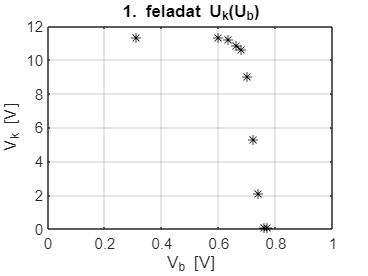


figure(); plot(V_in, V_out, "*k"); grid on;
title("1. feladat U_k(U_b)")
xlabel("V_b [V]");
ylabel("V_k [V]");
xlim([0 1])

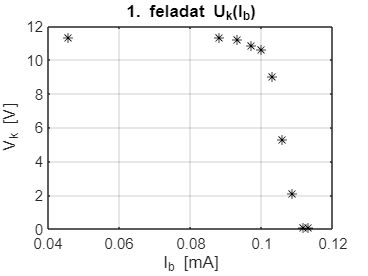


figure(); plot(I_b * 10^3, V_out, "*k"); grid on;
title("1. feladat U_k(I_b)")
xlabel("I_b [mA]");
ylabel("V_k [V]");

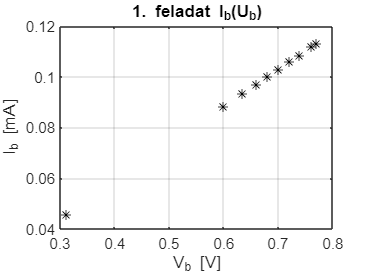


figure(); plot(V_in, I_b * 10^3, "*k"); grid on;
title("1. feladat I_b(U_b)")
xlabel("V_b [V]");
ylabel("I_b [mA]");

## 2. feladat

[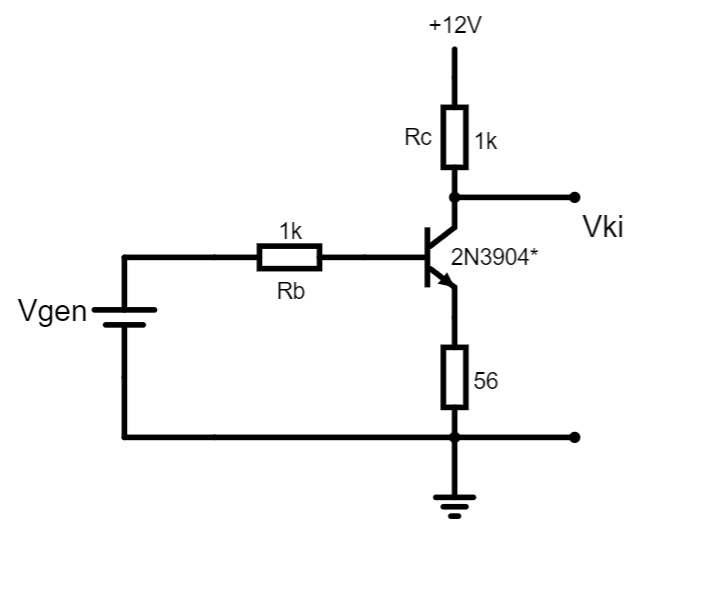](https://falstad.com/circuit/circuitjs.html?ctz=CQAgLCAMB0l3BWEBGGAmOaDsWDMkAONANgE5SsQFIrxcqBTAWmWQCgAXFYmjAkPgMJQUIFsmjkp5YrizxIaFNGRg0aXFOIZcuZHub9UNACYMAZgEMArgBsObAO5D+6iILRgakJy5SklQWQsYig2ACc-YNCg5CUaYx8ADxQCZBQwI1IkZAR0iDiQACUAYwjuXmECSv4E+DYU1noNBLRXXXAUJSKAIzYAcz98d2FdUO9fQWGQapBpnwA3OcCsJVxA4W9wLZ3oBF9Z6fW5yAgfZ2OjlfjfY8FZwR8iqML7ne2ukW89yeFogVWKBCYWcU1OALW4OSANCyAoAlIrjgnWQoQAagBrACWDTEaCQniUrzASAK6P6DAAdriMDFXghArkUYEAHKaU4AKnKHi8QyhVGIbFw-FIIAAYuktqgxOk0QB7eyWClsIA)

V_in = [0.33 0.6 ...
    0.7 0.8 0.883 1 1.1 1.195 ...
    1.35 1.43];
V_out = [11.39 11.34 ...
    10.62 9.3 8.13 5.78 4.65 3.15 ...
    0.75 0.75];

R = 6800;

I_b = V_in ./ R;

measurements = table(V_in', V_out', (I_b .* 10^3)', ...
    'VariableNames', ["Bemeneti feszültség (V)", "Kimeneti feszültség (V)", "Bemeneti áramerősség (mA)"]);
disp("Mért értékek");

Mért értékek


display(measurements);

measurements = 10×3 table
    Bemeneti feszültség (V)    Kimeneti feszültség (V)    Bemeneti áramerősség (mA)
    _______________________    _______________________    _________________________

              0.33                      11.39                     0.048529         
               0.6                      11.34                     0.088235         
               0.7                      10.62                      0.10294         
               0.8                        9.3                      0.11765         
             0.883                       8.13                      0.12985         
                 1                       5.78                      0.14706         
               1.1                       4.65                      0.16176         
             1.195                       3.15                      0.17574         
              1.35             

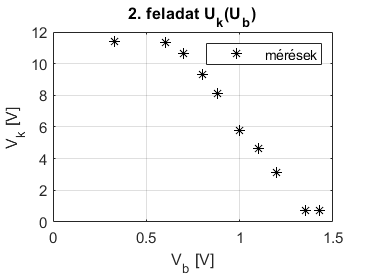


figure(); plot(V_in, V_out, "*k"); grid on;
title("2. feladat U_k(U_b)")
legend(["mérések"])
xlabel("V_b [V]");
ylabel("V_k [V]");
xlim([0 1.5])

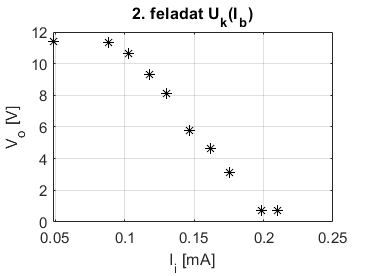


figure(); plot(I_b * 10^3, V_out, "*k"); grid on;
title("2. feladat U_k(I_b)")
xlabel("I_i [mA]");
ylabel("V_o [V]");

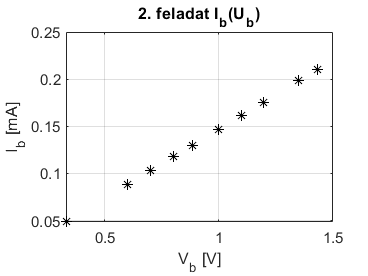


figure(); plot(V_in, I_b * 10^3, "*k"); grid on;
title("2. feladat I_b(U_b)")
xlabel("V_b [V]");
ylabel("I_b [mA]");

## 3. feladat

### 0 ohm emitter

A_in = [(21 * 10^-3) / 2, (22 * 10^-3) / 2, (18 * 10^-3) / 2];
A_out = [2.72 / 2, 3.35 / 2, 1.3 / 2];

amplification = A_out ./ A_in;
amplification_db = 20 .* log10(amplification);

measurements = table(A_in', A_out', amplification', amplification_db' , ...
    'VariableNames', ["Bemeneti jel amplitudó (V)", "Kimeneti jel amplitudó (V)", "Erősítés", "Erősítés (dB)"]);
disp("0 Ohm mérések");

0 Ohm mérések


display(measurements);

measurements = 3×4 table
    Bemeneti jel amplitudó (V)    Kimeneti jel amplitudó (V)    Erősítés    Erősítés (dB)
    __________________________    __________________________    ________    _____________

              0.0105                         1.36                129.52        42.247    
               0.011                        1.675                152.27        43.652    
               0.009                         0.65                72.222        37.173    


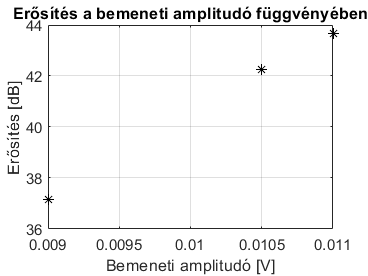


figure(); plot(A_in, amplification_db, "*k"); grid on;
title("Erősítés a bemeneti amplitudó függvényében");
xlabel("Bemeneti amplitudó [V]");
ylabel("Erősítés [dB]");

### 56 ohm emitter

A_in = [(26 * 10^-3) / 2, (22 * 10^-3) / 2, (17 * 10^-3) / 2];
A_out = [(312 * 10^-3) / 2, (140 * 10^-3) / 2, (55 * 10^-3) / 2];

amplification = A_out ./ A_in;
amplification_db = 20 .* log10(amplification);

measurements = table(A_in', A_out', amplification', amplification_db' , ...
    'VariableNames', ["Bemeneti jel amplitudó (V)", "Kimeneti jel amplitudó (V)", "Erősítés", "Erősítés (dB)"]);
disp("56 Ohm mérések");

56 Ohm mérések


display(measurements);

measurements = 3×4 table
    Bemeneti jel amplitudó (V)    Kimeneti jel amplitudó (V)    Erősítés    Erősítés (dB)
    __________________________    __________________________    ________    _____________

               0.013                         0.156                   12        21.584    
               0.011                          0.07               6.3636        16.074    
              0.0085                        0.0275               3.2353        10.198    


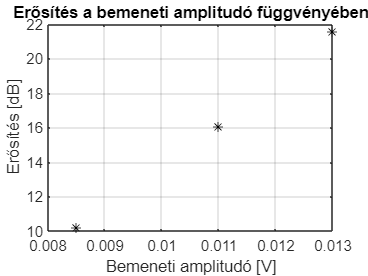


figure(); plot(A_in, amplification_db, "*k"); grid on;
title("Erősítés a bemeneti amplitudó függvényében");
xlabel("Bemeneti amplitudó [V]");
ylabel("Erősítés [dB]");

## meglepetés 7. labor 5. feladat

ezt  így megcsináltuk.